## Load SANS data

### Obtain matrix images from grasp depths

%Obtain matrix images from grasp depths: done and saved to GVS_grasp_data.mat
%{
Im=grasp_data(1).data1{1,6}(:,:,:);
BGR=grasp_data(3).data1{1,6}(:,:,:); %grasp_data(2): empty cell, grasp_data(3): blocked beam
I_0=Im-BGR;
%}

SANSdata=load('GVS_grasp_data.mat');
Im=SANSdata.Im;
BGR=SANSdata.BGR; 
I_0=Im-BGR;
save('I0_orig_1deg.mat','I_0')

### Image conditioning

%Center positions
c_x=61;
c_y=65;
pix_x=128;
pix_y=128;
Rmax=30; %forward scattered intensity

I_0=SANS_image_conditioning(I_0,c_x,c_y,pix_x,pix_y,Rmax);


#### Test image

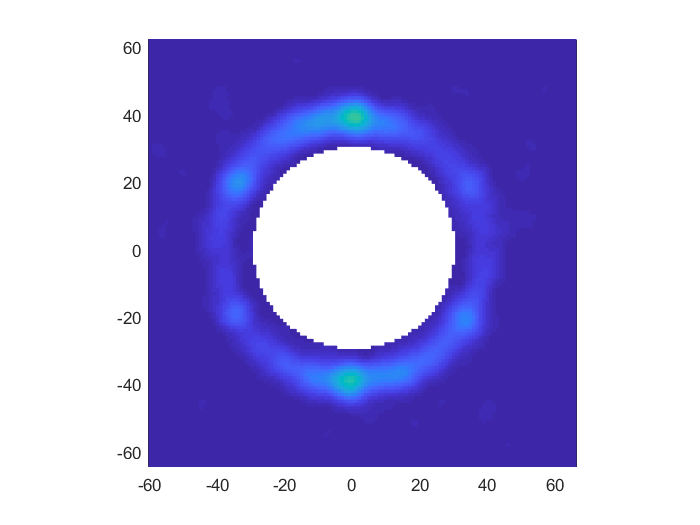

figure(12)
cla
x=0.5-c_x:1:pix_x-c_x-0.5;
z=0.5-c_y:1:pix_y-c_y-0.5;
[X,Z]=meshgrid(x,z);
pcolor(X,Z,I_0(:,:,11)); shading flat;
caxis([0,70])
axis square

## Append SANS intensity maps to a cylindrical grid

### Separate the two halves of the inensity map in each angular slice

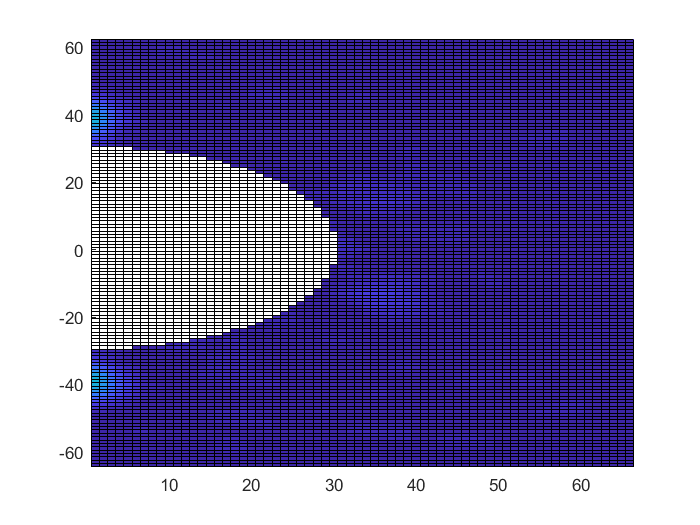

%Intensity map in cylindrical mesh
%Separate the two halves of the inensity map in each angular slice
I_right=I_0(:,c_x+1:end,:);
figure(13)
cla
xr=0.5:1:66.5;
zr=0.5-c_y:1:pix_y-c_y-0.5;
[Xr,Zr]=meshgrid(xr,zr);
pcolor(Xr,Zr,I_right(:,:,2)); 
caxis([0,70])

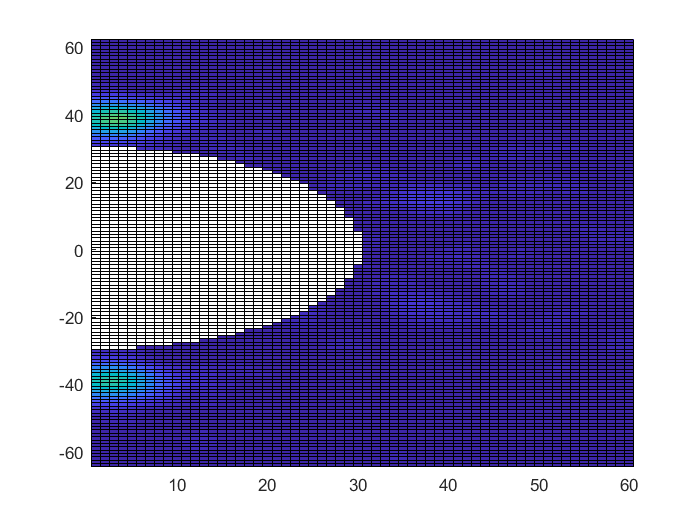


I_left=I_0(:,c_x:-1:1,:);
figure(14)
cla
xl=0.5:1:60.5;
zl=0.5-c_y:1:pix_y-c_y-0.5;
[Xl,Zl]=meshgrid(xl,zl);
pcolor(Xl,Zl,I_left(:,:,2));
caxis([0,70])

### Create cylindrical grid for original data

r=0.5:1:60.5;
z=0.5-c_y:1:pix_y-c_y-0.5;
phi_deg=10:10:370; phi_rad=phi_deg*pi/180;

[phimesh,rmesh,zmesh]=meshgrid(phi_rad,r,z);
phimesh=permute(phimesh,[2,1,3]);
rmesh=permute(rmesh,[2,1,3]);
zmesh=permute(zmesh,[2,1,3]);

phi_dense_deg=10:1:370; phi_dense_rad=phi_dense_deg*pi/180;
[phimesh_dense,rmesh_dense,zmesh_dense]=meshgrid(phi_dense_rad,r,z);

### Assign the intensity data to the cylindrical grid

I_cyl=cat(3,I_right(:,1:61,2:19),I_left(:,:,2:20));
I_cyl=permute(I_cyl,[3,2,1]);
save('GVS_volumetric_polar_sm.mat','I_cyl')

#### Test cylindrical intensity map

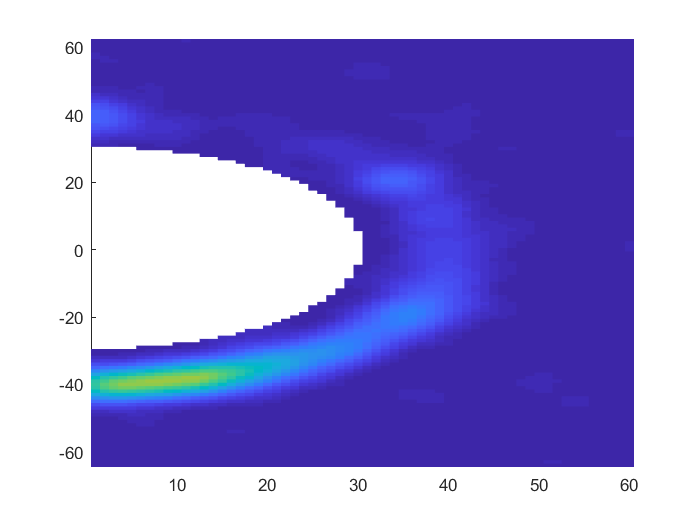

figure(15)
ind=35;
cla
X=squeeze(rmesh(ind,:,:));
Y=squeeze(zmesh(ind,:,:));
I=squeeze(I_cyl(ind,:,:));
pcolor(X,Y,I);
%hold on
%contour(X,Y,I,[1,2,3,4,5,6],'Color','r');
shading flat;
caxis([0,70])

## Convert cylindrical grid to a Cartesian grid

### Original cylindrical grid in Cartesian coordinates

The original cylindrical grid is expressed as cartesian coordinates. Note that the resulting grid is not spaced uniformly.

[X_cyl,Y_cyl,Z_cyl]=pol2cart(phimesh,rmesh,zmesh);
save('Cylinder_mesh_cart.mat','X_cyl','Y_cyl','Z_cyl')

[X_cyl_dense,Y_cyl_dense,Z_cyl_dense]=pol2cart(phimesh_dense,rmesh_dense,zmesh_dense);
save('Cylinder_mesh_dense_cart.mat','X_cyl_dense','Y_cyl_dense','Z_cyl_dense')

### New equidistant Cartesian grid inside the cylinder

A new Cartesian grid is created which has equidistant spacing in qx,qy,qz for later interpolation

xcart=-50:1:50;
ycart=-50:1:50;
zcart=0.5-c_y:1:pix_y-c_y-0.5;
[Xc,Yc,Zc]=meshgrid(xcart,ycart,zcart);
save('Cartesian_mesh.mat','Xc','Yc','Zc')



## Interpolate data to the grids

### Interpolate SANS intensity data for the new equidistant Cartesian grid expressed in Cartesian coordinates

Interpolation is time consuming, data is saved already

I_cart_cartint=griddata(X_cyl,Y_cyl,Z_cyl,I_cyl,Xc,Yc,Zc); %interpolation according to Cartesian metric
save('GVS_volumetric_cart_sm.mat','I_cart_cartint')
I_temp=load('GVS_volumetric_cart_sm.mat','I_cart_cartint');
I_cart_cartint=I_temp.I_cart_cartint;

### Interpolate SANS intensity data for the new equidistant Cartesian grid expressed in Cylindrical coordinates

[Phi_c,R_c,Z_c]=cart2pol(Xc,Yc,Zc);
I_cart_cylint=griddata(phimesh,rmesh,zmesh,I_cyl,Phi_c,R_c,Z_c); %interpolation according to Cylindrical metric
save('GVS_volumetric_cyl_sm.mat','I_cart_cylint')
I_temp=load('GVS_volumetric_cyl_sm.mat','I_cart_cylint');
I_cart_cylint=I_temp.I_cart_cylint;

I_cyl_cylint=griddata(phimesh,rmesh,zmesh,I_cyl,phimesh_dense,rmesh_dense,zmesh_dense);
save('GVS_volumetric_cyl_sm.mat','I_cyl_cylint')
I_temp=load('GVS_volumetric_cyl_sm.mat','I_cyl_cylint');
I_cyl_cylint=I_temp.I_cyl_cylint;

### Test graphs

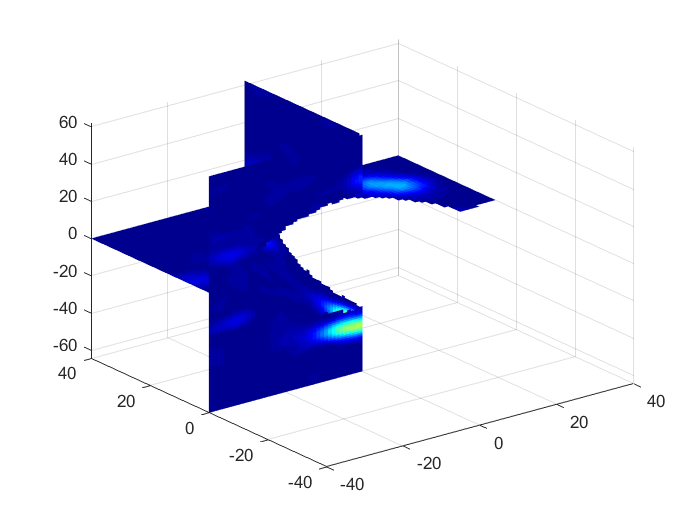

figure(16)
slice(Xc,Yc,Zc,I_cart_cylint,[0],[0],[0])
colormap(jet)
caxis([0,70])
shading flat

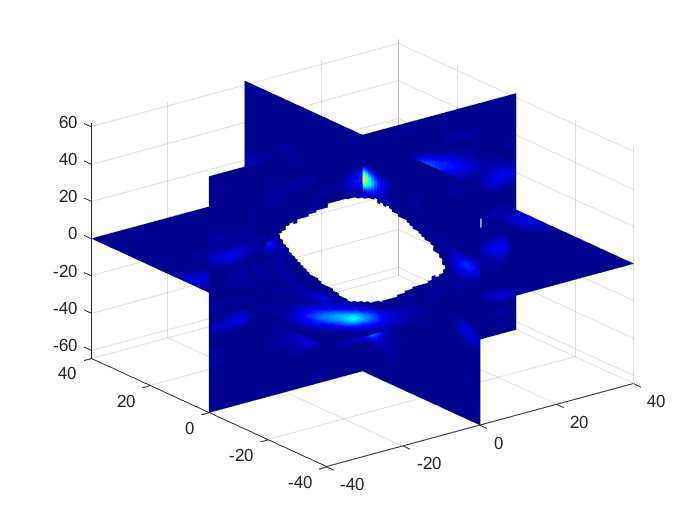


figure(17)
slice(Xc,Yc,Zc,I_cart_cartint,[0],[0],[0])
colormap(jet)
caxis([0,70])
shading flat

## Save relevant grid and SANS intensity

I_cart_cartint=permute(I_cart_cartint,[2,1,3]);
Xc=permute(Xc,[2,1,3])/100; 
Yc=permute(Yc,[2,1,3])/100;
Zc=permute(Zc,[2,1,3])/100;
save('Cartesian_mesh_Lab.mat','Xc','Yc','Zc'); %meshgrid in [Qx,Qy,Qz] order in nm^-1 units 
save('GVS_intensity_raw.mat','I_cart_cartint'); %Raw intensity data in [Qx,Qy,Qz] order in arbitrary units